## Final exam  21-06-2023

### Problem 1

We wish to study how the temperature varies with depth in a swimming pool (see Figure below). For that, we take a vertical segment from the bottom to the surface at the pool midpoint, and mesh it with 3 linear elements of equal length as shown in the image.

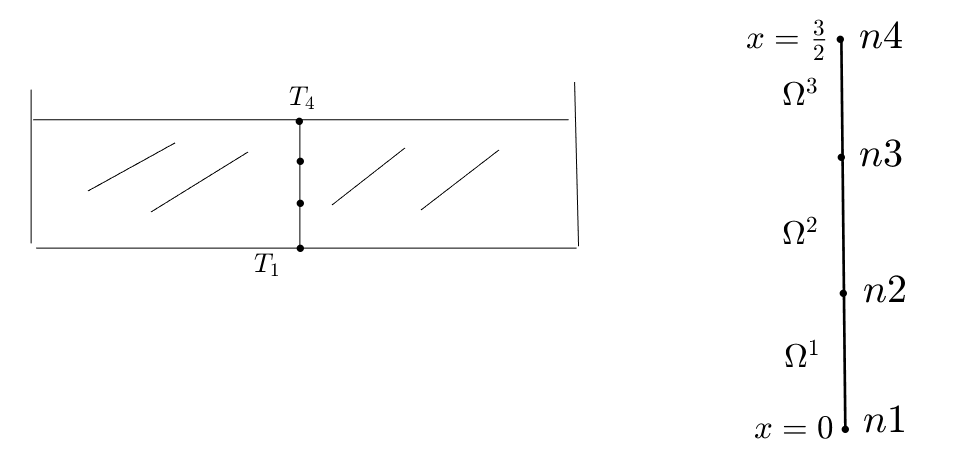

The water temperature follows the 1D Poisson equation $-k_{c}\frac{\mathrm{d} T}{\mathrm{d} x} = f(x)$, where $k_{c}$ is the thermal conductivity of the water, which we approximate as $0.5\frac{\text{W}}{\text{m}^{\circ}\text{C}}$, and the internal heat source is the warming of the pool by sunlight, with a power density $f(x) = (6x + 3)\frac{\text{W}}{\text{m}^{3}}$ ($x$ is the height above the pool bottom in $\text{m}$). The pool bottom is always at a temperature $T_{1} = 18^{\circ}\text{C}$, and the temperature at the pool surface has been measured to be $T_{4} = 26^{\circ}\text{C}$.

(a) (2 points) The trace of the stiffness matrix $K$ of the global system is:

**Solution.**

The local stiffness matries are $K^{e} = \left(\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\right)$, $e = 1, 2, 3$; so the global stifness matrix is:

$K = \left(\begin{array}{rrrr}
 1 & -1 &     &   \\
-1 &  2 & -1 &   \\
    & -1 &  2 &  -1\\
    &     &  -1 & 1
\end{array}\right)  $,

and therefore $\text{tr}~K = \sum\limits_{i=1}^{4} K_{ii} = 6$.

Let's try it with Matlab:

clearvars
close all
Ke = [1,-1; -1, 1];
elem = [1, 2; 2, 3; 3, 4];
nodes = [0; 0.5; 1.0; 1.5];

numElem = size(elem,1);
numNodes = size(nodes,1)

numNodes = 4

K = zeros(numNodes);
for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    K(rows, cols) = K(rows, cols) + Ke;
end
K

K =      1    -1     0     0
    -1     2    -1     0
     0    -1     2    -1
     0     0    -1     1


fprintf('trace of  stiffness matrix, K, tr K = %.1f\n', trace(K))

trace of  stiffness matrix, K, tr K = 6.0


(b) (4 points) Find the load vector component $F_{3}$ exactly (**do not** approximate $f$ as constant in the elements).

**Solution.**

We need the shape funcions of the 2nd element's 2nd local node and of the 3rd elements 1st local node:


$$\Psi_{2}^{2}(x) = \frac{x-1/2}{1-1/2} = 2\left(x-\frac{1}{2}\right),\qquad
\Psi_{1}^{3}(x) = \frac{x-3/2}{1-3/2} = 2\left(\frac{3}{2} - x\right).
$$


Then:


$$\begin{array}{l}
F^{2}_{2} = \int_{1/2}^{1} f(x)\Psi_{2}^{2}(x)\,\mathrm{d}x = 
 12 \int_{1/2}^{1}\left (x + \frac{1}{2}\right)\left(x-\frac{1}{2}\right)\,\mathrm{d}x = 
12\int_{0}^{1/2}\!\! t(t+1)\,\mathrm{d}t
 = 12\left[\frac{t^{3}}{3} + \frac{t^{2}}{2}\right]_{t = 0}^{t=1/2}\\
\qquad = 12\left(\frac{1}{24} + \frac{1}{8}\right) = \frac{1}{2} + \frac{3}{2} = 2,\\
F^{3}_{1} = \int_{1}^{3/2}\!\!\! f(x)\Psi_{3}^{1}(x)\,\mathrm{d}x = 
 12\int_{1}^{3/2}\! \left(\frac{3}{2}-x\right)\left(x +\frac{1}{2} \right)\,\mathrm{d}x =
12\int_{0}^{1/2}\!\! t\left(2 - t\right)\,\mathrm{d} t
= 12\left[t^{2} - \frac{t^{3}}{3}\right]_{t = 0}^{t=1/2}\\
\qquad = 12\left(\frac{1}{4} - \frac{1}{24}\right) = 3 - \frac{1}{2} = \frac{5}{2}. 
\end{array}$$


and therefore $F_{3} = F^{2}_{2} + F^{3}_{1} = 2 + \frac{5}{2} =  \frac{9}{2} =  4.5$.

If we want to compute the other components ($F_{1}, F_{2}$, and $F_{4}$) of the load force vector, we also need all the rest of the shape funcitons. Straightforward computation yields,


$$\Psi_{1}^{1}(x) = 2\left(\frac{1}{2} - x\right),\quad 
 \Psi_{1}^{2}(x) = 2x, \quad
 \Psi_{2}^{1}(x) = 2\left(1 - x\right), \quad  
\Psi_{3}^{2}(x) = 2\left(x - 1\right).$$


Hence, 


$$\begin{array}{l}
F_{1}^{1} = \int_{0}^{1/2}\!\!\! f(x)\Psi_{1}^{1}(x)\,\mathrm{d}x =
12\int_{0}^{1/2}\! \left(x + \frac{1}{2}\right)\left(\frac{1}{2} - x\right)\, \mathrm{d}x = 
12 \int_{0}^{1/2}\!\left(\frac{1}{4} - x^{2}\right)\,\mathrm{d} x =
12\left[\frac{x}{4} - \frac{x^{3}}{3}\right]_{x=0}^{x=1/2}\\
\qquad =
12\left(\frac{1}{8} - \frac{1}{24}\right) =\frac{3}{2} - \frac{1}{2} = 1,\\ 
%%%
F_{2}^{1} = \int_{0}^{1/2}\!\!\! f(x) \Psi_{2}^{1}(x)\,\mathrm{d}x = 
 12\int_{1/2}^{1}\! \left(x + \frac{1}{2}\right) x\,\mathrm{d}x =
12\left[\frac{x^{3}}{3} + \frac{x^{2}}{4}\right]_{x = 0}^{x=1/2}\\
\qquad = 12\left(\frac{1}{24} + \frac{1}{16}\right) =
 \frac{1}{2} + \frac{3}{4} = \frac{5}{4},\\
%%%
F_{1}^{2} = \int_{1/2}^{1}\! f(x) \Psi_{1}^{2}(x)\,\mathrm{d}x = 
 12\int_{1/2}^{1}\! \left(x + \frac{1}{2}\right)
\left(1 - x\right)\,\mathrm{d}x =
12\int_{0}^{1/2}\! t\left(\frac{3}{2} - t\right)\,\mathrm{d}t =
12\left[\frac{3 t^{2}}{4} - \frac{t^{3}}{3}\right]_{t=0}^{t = 1/2}\\
\qquad = 12\left(\frac{3}{16} - \frac{1}{24}\right) = 
\frac{9}{4} - \frac{1}{2} = \frac{7}{4},\\
%%% 
F_{2}^{3} =
 \int_{1}^{3/2}\!\!\! f(x) \Psi_{2}^{3}(x)\,\mathrm{d}x =
12\int_{1}^{3/2}\! \left(x + \frac{1}{2}\right)
\left(x -1\right)\,\mathrm{d}x =
12\int_{0}^{1/2}\! t\left(t + \frac{3}{2}\right)\,\mathrm{d} t =
12\left[\frac{t^{3}}{3} + \frac{3 t^{2}}{4}\right]_{t = 0}^{t = 1/2}\\
\qquad = 12\left(\frac{1}{24} + \frac{3}{16}\right) = \frac{1}{2} + \frac{9}{4} = \frac{11}{4}. 
\end{array}$$


and therefore


$$F_{1} = F_{1}^{1} = 1,\qquad
F_{2} = F_{2}^{1} + F_{1}^{2} = \frac{5}{4} + \frac{7}{4} = 3, \qquad
F_{4} = F_{2}^{3} = \frac{11}{4} = 2.75.$$


Let's do the same with Matlab: 

f = @(x) 6*x + 3;
F = zeros(4,1);
syms x % create a symbolic variable
for e = 1:numElem
    rows = [elem(e,1), elem(e,2)]; nod = nodes(rows); 
    h = nod(2)-nod(1);
    Psi = @(x) [-x + nod(2); x-nod(1)]/h;
    Fe = int(f(x)*Psi(x),nod(1),nod(2));
    F(rows) = F(rows) + Fe;
end
clear x % remove symbolic variable from memory, no longer needed
fprintf(['(b) F(3) = %.4f W/m^2\n',...)
         '    Hint. The other components of F are (in W/m^2): ',...
         'F(1) = %.4f, F(2) = %.4f, F(4) = %.4f.'],...
         F(3), F([1,2,4]))

(b) F(3) = 4.5000 W/m^2
    Hint. The other components of F are (in W/m^2): F(1) = 1.0000, F(2) = 3.0000, F(4) = 2.7500.

which coincides with the computations already made by hand.

(c) (4 points) With the given boundary conditions and values of F , and assuming no convection, find the maximal water temperature amongt he nodes $n_{1} , n_{2} , n_{3}$, and $n_{4}$ .

**Solution.**

The coupled system is giuven by,


$$ \left(\begin{array}{rrrr}
 1 & -1 &     &   \\
-1 &  2 & -1 &   \\
    & -1 &  2 &  -1\\
    &     &  -1 & 1
\end{array}\right)  
\left(
\begin{array}{c}
T_{1}\\
T_{2}\\
T_{3}\\
T_{4}
\end{array}
\right) =
\left(
\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}
\end{array}
\right)
 +
\left(
\begin{array}{c}
1\\
3\\
9/2\\
11/4
\end{array}
\right),$$


whereas the boundary conditons, as deduced from the text are:

- Natural: $Q_{2} = Q_{3} = 0$,

- Essential: $T_{1} = 18$, $T_{4} = 26$.

After setting these boundary conditions in the coupled system above, the reduced system casts,


$$\left.
\begin{array}{rcl}
2 T_{2} - T_{3}\!\!\!\!\! &=&\!\!\!\!\! 3 + T_{1} = 3  + 18 = 21,\\
-T_{2} + 2T_{3}\!\!\!\!\! &=&\!\!\!\!\! \frac{9}{2} + T_{4} = \frac{9}{2} + 26 = \frac{61}{2}
\end{array}
\right\}
\, \text{ or, in matrix notation: }
\left(
\begin{array}{rr}
2 & -1\\
-1 & 2
\end{array} 
\right)
\left(
\begin{array}{c}
T_{2}\\
T_{3}
\end{array}
\right) = 
\left(
\begin{array}{c}
21\\
61/2
\end{array}
\right).$$


The solution of this last system is: $T_{2} = \frac{145}{6} = 24.1\overline{6}$, $T_{3} = \frac{82}{3} = 27.\overline{3}$; so the maximal water temperature among the nodes $n_{1}, n_{2}, n_{3}, n_{4}$ is:


$$\max\left\{T_{1}, T_{2}, T_{3}, T_{4}\right\} =
\max\left\{18, \frac{145}{6}, \frac{82}{3}, 26\right\} =
\max\left\{18, 24.1\overline{6}, 27.\overline{3}, 26\right\} = 
27.\overline{3}^{\circ}\text{C}$$


Finally, we can substitute the (now) known values of the temperatures $T_{1}$, $T_{2}$, $T_{3}$ and $T_{4}$ in the 1st and 4th equations of the coupled system to find $Q_{1}$ and $Q_{4}$. Thus:


$$\begin{array}{l}
Q_{1} = T_{1} - T_{2} - 1 = 18 - \frac{145}{6} - 1 = -\frac{43}{6} = -7.1\overline{6},\\
Q_{4} = -T_{3} + T_{4} - \frac{11}{4} =
-\frac{82}{3} + 26 - \frac{11}{4} =
 -\frac{49}{12} = -4.08\overline{3}.  
\end{array}$$


As before, we can compute all these quantities using Matlab code:

Q = zeros(numNodes, 1);
u = zeros(numNodes, 1);

% fixed nodes
fixedNods = [1,numNodes];
freeNods = setdiff(1:numNodes, fixedNods);

% Boundary conditions

% Natural
Q(freeNods) = 0; %Not necessary, since Q is initialised to 0

% Essential
u(1) = 18.0;
u(numNodes) = 26.0;

% Reduced system
Fm = F(freeNods) + Q(freeNods) - K(freeNods, fixedNods)*u(fixedNods);
Km = K(freeNods, freeNods);

% Solution of the reduced system
um = Km\Fm;

% Add the solution of the reduced system to the corresponding componets of
% the global solution
u(freeNods) = um;

% Post process 

% Compute the flows Q
Q = K*u - F;

% Set up a table showing temperature and flow at each node 
sz = [numNodes, 3];
varTypes = ["int64", "double", "double"];
varNames = ["node", "T(ºC)", "Q(W/m^2)"];
sols = table('Size', sz, 'VariableTypes', varTypes, 'VariableNames', varNames);
sols(:,1) = table((1:numNodes)'); sols(:,2) = table(u); sols(:,3) = table(Q);

sols %Show the table with the solutions 

sols = 4×3 table
    node    T(ºC)      Q(W/m^2)  
    ____    ______    ___________

     1          18        -7.1667
     2      24.167    -3.5527e-15
     3      27.333              0
     4          26        -4.0833


fprintf(['(c) Maximum water temperature among the nodes is: %.4f%cC\n', ...
         '    Hint. Q1 = %.4f (W/m^2)\n'], max(u), char(176), Q(1))

(c) Maximum water temperature among the nodes is: 27.3333°C
    Hint. Q1 = -7.1667 (W/m^2)
